# **Visión Artificial - Sistemas de Visión Artificial**

# **Práctica 3. Segmentación de imágenes (II)**

**Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel.**

 **Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es): Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha:** 30/10/2026

Este mlx contiene la parte de la práctica 3 relacionada con la segmentación basada en bordes y con el uso de la transformada de Hough para detectar rectas y circunferencias. También se incluye un ejercicio de segmentación basada en regiones mediante la transformada watershed.

La **entrega** se realizará en el Aula Virtual de la asignatura: Contenidos --> Entregables --> Práctica 3.

**Ejercicios propuestos:**

**1. Transformada watershed:**

- Cargue la imagen `'circles.png'` umbralízela y realice una segmentación utilizando la transformada watershed. Analice si se produce sobresegmentación. En caso afirmativo, intente reducirla mediante preprocesado morfológico.

% 1. TRANSFORMADA WATERSHED
clear all
close all

%Cargar y umbralizar
info=imfinfo('.\Imagenes\circles.png');
disp(info.ColorType) % Tanto las imágenes en escala de grises como las binarias devuelven la cadena 'grayscale'

grayscale


disp(info.BitDepth) % Si es 1, significa que cada píxel solo puede tener 2 valores (2^1), por lo tanto, es binaria

     1



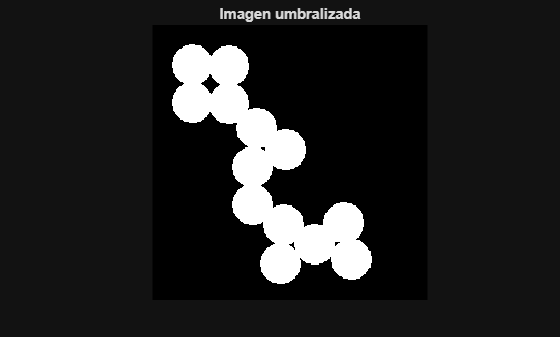


BW = imread('.\Imagenes\circles.png'); % Ya es binaria, no hace falta umbralizar

figure;
imshow(BW); title('Imagen umbralizada');

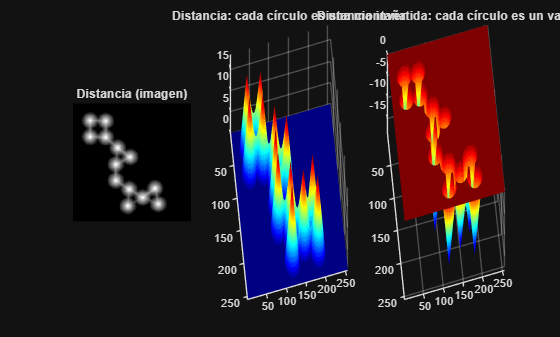


% Transformada de distancia
% A cada píxel del objeto se le asigna su distancia al fondo más cercano.
% bwdist calcula la distancia al píxel BLANCO más cercano, por eso se lo aplicamos a ~BW
% (el fondo pasa a ser blanco) -> obtenemos la distancia de cada píxel del círculo al fondo.
D = bwdist(~BW);


figure;
subplot(1,3,1), imshow(D, []); title('Distancia (imagen)');

subplot(1,3,2), surf(D, 'EdgeColor', 'none');
axis ij;            % fila 1 arriba, igual que en la imagen -> misma orientación
axis tight;         % ajusta los ejes a la imagen
view(-10, 65);      % casi desde arriba y un poco inclinada: cada pico encima de su círculo
colormap(gca, jet);
title('Distancia: cada círculo es una montaña');

subplot(1,3,3), surf(-D, 'EdgeColor', 'none');
axis ij; axis tight; view(-10, 65);
colormap(gca, jet);
title('Distancia invertida: cada círculo es un valle');


%% Watershed directo (sin preprocesado)
% Invertimos la distancia: las cimas (centros) pasan a ser valles, que es lo que inunda watershed.
relieve = -D;

% (Si a una matriz de etiquetas le pones una máscara lógica entre paréntesis, MATLAB busca y modifica únicamente los píxeles donde la máscara vale 1.
% Esto es lo que se hace con las mascaras relieve y L para modificar el fondo (valores a 1 tras invertir la imagen))
relieve(~BW) = -Inf; %El fondo de la imagen se pone a −∞, el valle más profundo posible. Así el fondo forma su propia cuenca y no se mezcla con los círculos.

L = watershed(relieve); % cada cuenca recibe una etiqueta 1, 2, 3...; las líneas divisorias valen 0
L(~BW) = 0; % El fondo se pone a 0

numRegionesCirculos = numel(unique(L(L > 0))); % contamos las etiquetas positivas que quedan tras quitar el fondo
disp(['Regiones sin contar huecos y fondo: ' num2str(numRegionesCirculos)]);

Regiones sin contar huecos y fondo: 17


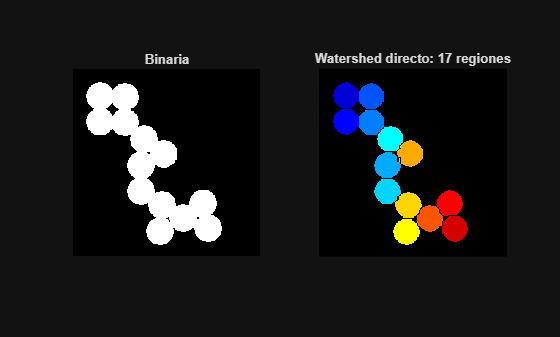


figure;
subplot(1,2,1), imshow(BW); title('Binaria');
subplot(1,2,2), imshow(label2rgb(L, 'jet', 'k')); % cada región de un color, fondo negro
title(['Watershed directo: ' num2str(numRegionesCirculos) ' regiones']);



%% Reducir la sobresegmentación con preprocesado morfológico (marcadores)
% Idea (apuntes): obtener regiones que sabemos CON SEGURIDAD que son objeto -> marcadores.
% Erosionando mucho, cada círculo queda reducido a un "núcleo" en su centro y los círculos
% que se tocan se separan. Cada núcleo será el ÚNICO punto de partida del agua en ese círculo.
radio = 12; %El radio 12 permite separar las zonas de contacto entre círculos y conservar un marcador interior para cada uno
marcadores = imerode(BW, strel('disk', radio));

% imimposemin obliga a que los únicos valles del relieve estén en los marcadores (elimina los mínimos falsos que causaban la sobresegmentación)
relieve2 = imimposemin(-D, marcadores);
relieve2(~BW) = -Inf;

L2 = watershed(relieve2);
L2(~BW) = 0; % SOLO en el fondo, pon 0

numRegionesCirculos2 = numel(unique(L2(L2 > 0))); % contamos las etiquetas positivas que quedan tras quitar el fondo
disp(['Regiones sin contar huecos y fondo: ' num2str(numRegionesCirculos2)]);

Regiones sin contar huecos y fondo: 13


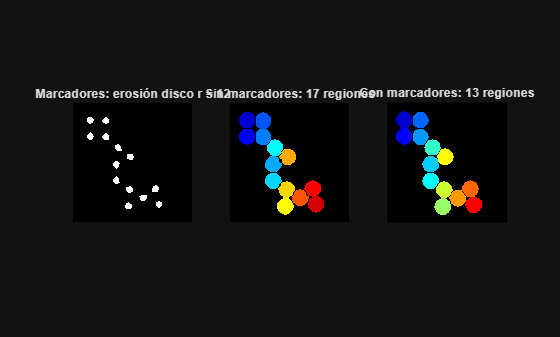


figure;
subplot(1,3,1), imshow(marcadores); title(['Marcadores: erosión disco r = ' num2str(radio)]);
subplot(1,3,2), imshow(label2rgb(L,  'jet', 'k')); title(['Sin marcadores: ' num2str(numRegionesCirculos) ' regiones']);
subplot(1,3,3), imshow(label2rgb(L2, 'jet', 'k')); title(['Con marcadores: ' num2str(numRegionesCirculos2) ' regiones']);

Se ha segmentado la imagen “circles.png”, formada por 13 círculos que se tocan entre sí, mediante la transformada watershed. La imagen original ya es binaria, por lo que no es necesario umbralizarla. A continuación se calculó la transformada de distancia (bwdist), en la que cada píxel del objeto toma el valor de su distancia al fondo, de modo que los centros de los círculos aparecen como máximos. Se invirtió para convertirlos en mínimos (cuencas) y se aplicó watershed. Hay que tener en cuenta que entre los círculos que se tocan quedan huecos de fondo "encerrados" entre círculos y sin conexión con el fondo exterior. Debido a que watershed es segmentación basada en regiones, estos huecos deben considerarse regiones separadas, aunque luego se puedan fiiltrar. El resultado presenta sobresegmentación: se obtienen 17 regiones en lugar de 13, debido a regiones diminutas situadas en las uniones entre círculos. Su origen es que el agua sale de todos los valles del relieve, por muy pequeños que sean: si los estrechamientos entre círculos generan pequeños mínimos locales falsos, watershed trata cada uno como un valle más, dándole su propio color de agua. 

Para eliminarlo se aplicó un preprocesado morfológico: erosionando la imagen binaria con un disco de radio 12 se obtiene un núcleo en el centro de cada círculo, que se utiliza como marcador; imponiendo que los únicos mínimos del relieve sean estos marcadores (imimposemin), watershed obtiene correctamente las 13 regiones.

**2. Segmentación basada en bordes:**

- Abra la imagen "coins.png".

- Detecte los bordes mediante Canny. Utilice controles deslizantes para modificar los umbrales y/o σ, visualice el efecto de las distintas configuraciones y comente cómo afecta cada parámetro al resultado.

- Intente conectar los bordes separados por pequeños huecos mediante dilatación (`imdilate`). Visualice el resultado.

- Rellene los contornos obtenidos.

- Segmente los distintos objetos, etiquetándolos con *bwlabel* y muestre el resultado final.

- Repita los pasos 1 a 5 utilizando la máscara de `'sobel'` `y` compare los resultados Canny - Sobel. Justifique las diferencias.

- Repita los pasos 1 a 5 y compare los resultados realizando o no la dilatación (paso 3). Justifique.

- Compare los resultados obtenidos al utilizar diferentes elementos estructurantes en la dilatación. Justifique.

- Compare los resultados realizando una dilatación (*imdilate*) o un cierre (*imclose*). Justifique.

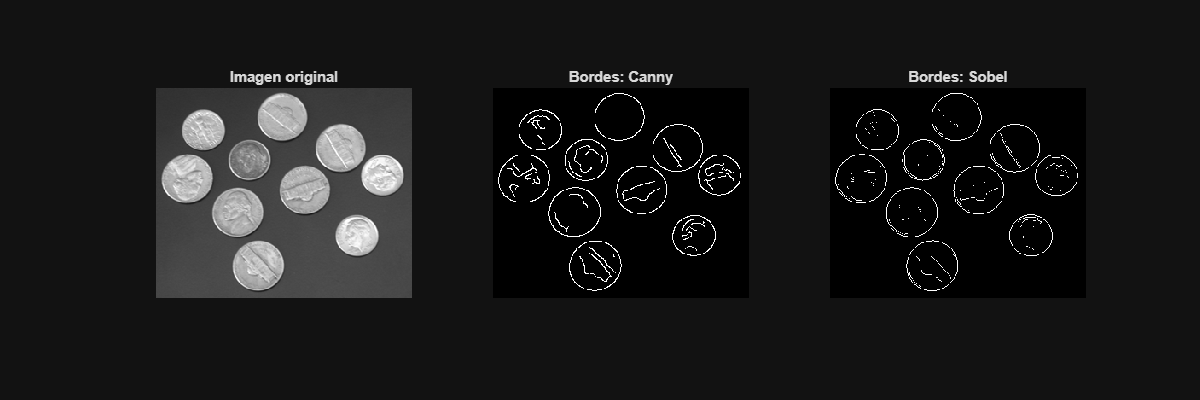


clear all
close all
I = imread('.\Imagenes\coins.png');

% ---- 1) BORDES: Canny y Sobel ----
% Los controles del Live Editor permiten cambiar los parámetros y ejecutar la sección.
umbralAlto = 0.2;
sigma = 2;
umbralBajo = umbralAlto / 2; % Canny enlaza bordes débiles conectados a bordes fuertes
bordesCanny = edge(I, 'Canny', [umbralBajo umbralAlto], sigma);

% Sobel usa un único umbral. El factor permite variar el valor automático.
[~, umbralSobelAuto] = edge(I, 'Sobel');

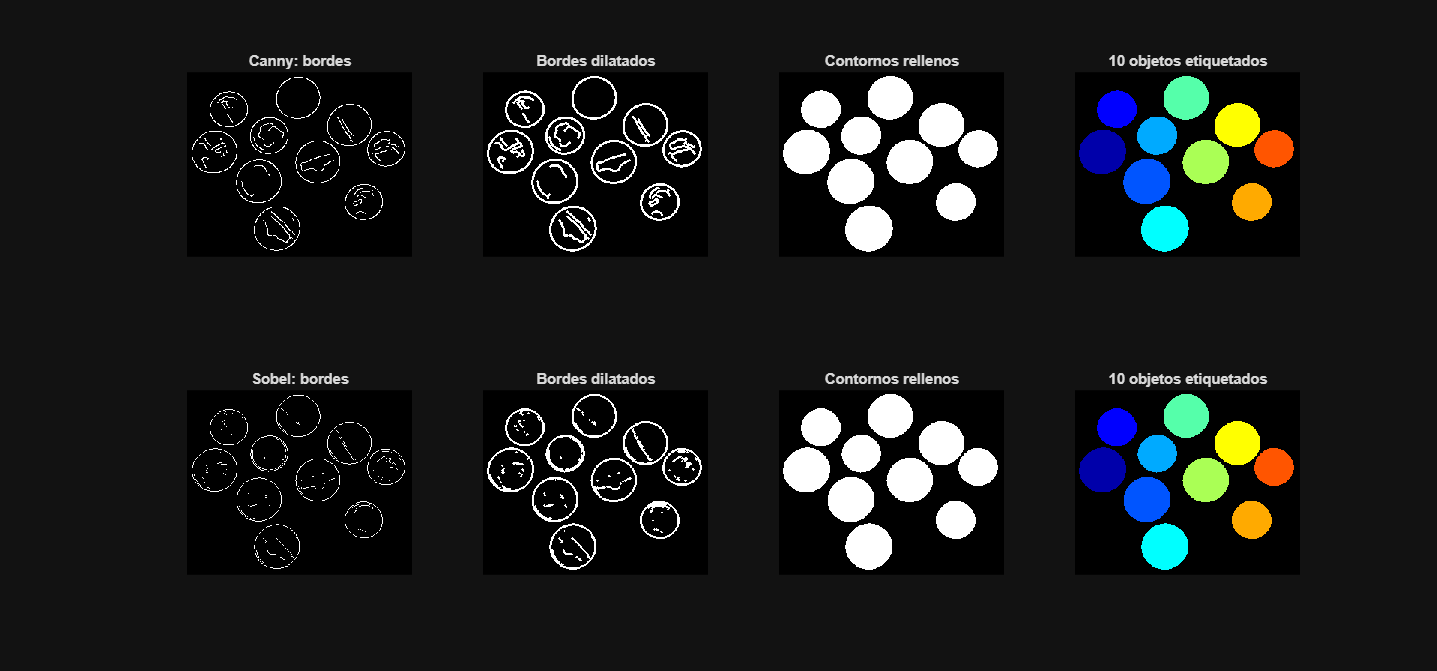

Canny con dilatación: 10 objetos
Sobel con dilatación: 10 objetos


factorSobel = 1;
bordesSobel = edge(I, 'Sobel', factorSobel * umbralSobelAuto);

% Primero vemos qué bordes encuentra cada método en la misma imagen.
figure('Position', [100 100 1200 400]);
subplot(1,3,1), imshow(I); title('Imagen original');
subplot(1,3,2), imshow(bordesCanny); title('Bordes: Canny');
subplot(1,3,3), imshow(bordesSobel); title('Bordes: Sobel');

% ---- 2) DILATAR, RELLENAR Y ETIQUETAR ----
% Seguimos los pasos del ejemplo de clase con los dos detectores.
elemento = strel('disk', 1, 0);
bordes = {bordesCanny, bordesSobel};
metodos = {'Canny', 'Sobel'};
figure('Position', [100 100 1500 700]);
for k = 1:2
    unidos = imdilate(bordes{k}, elemento); % conecta pequeños cortes del contorno
    rellenos = imfill(unidos, 'holes'); % sólo rellena los contornos cerrados
    [etiquetas, numero] = bwlabel(rellenos);

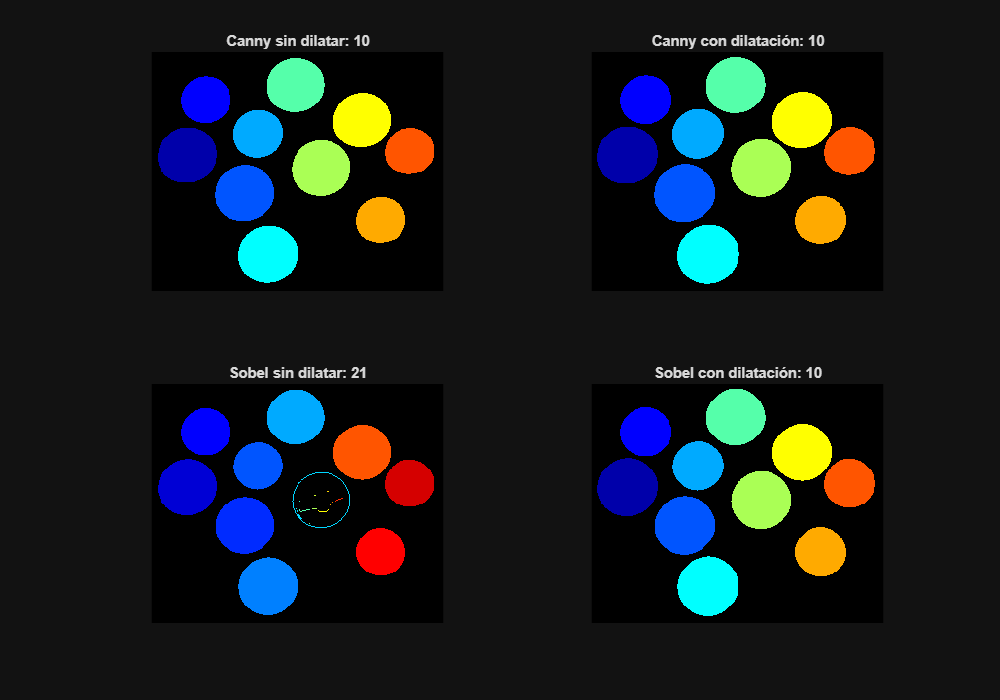

    fprintf('%s con dilatación: %d objetos\n', metodos{k}, numero);

    subplot(2,4,(k-1)*4+1), imshow(bordes{k}); title([metodos{k} ': bordes']);
    subplot(2,4,(k-1)*4+2), imshow(unidos); title('Bordes dilatados');
    subplot(2,4,(k-1)*4+3), imshow(rellenos); title('Contornos rellenos');
    subplot(2,4,(k-1)*4+4), imshow(label2rgb(etiquetas, 'jet', 'k'));
    title([num2str(numero) ' objetos etiquetados']);
end

% ---- 3) COMPARACIÓN: con y sin dilatación, para ambos detectores ----
% Así se ve si unir los cortes realmente ayuda a rellenar las monedas.
figure('Position', [100 100 1000 700]);

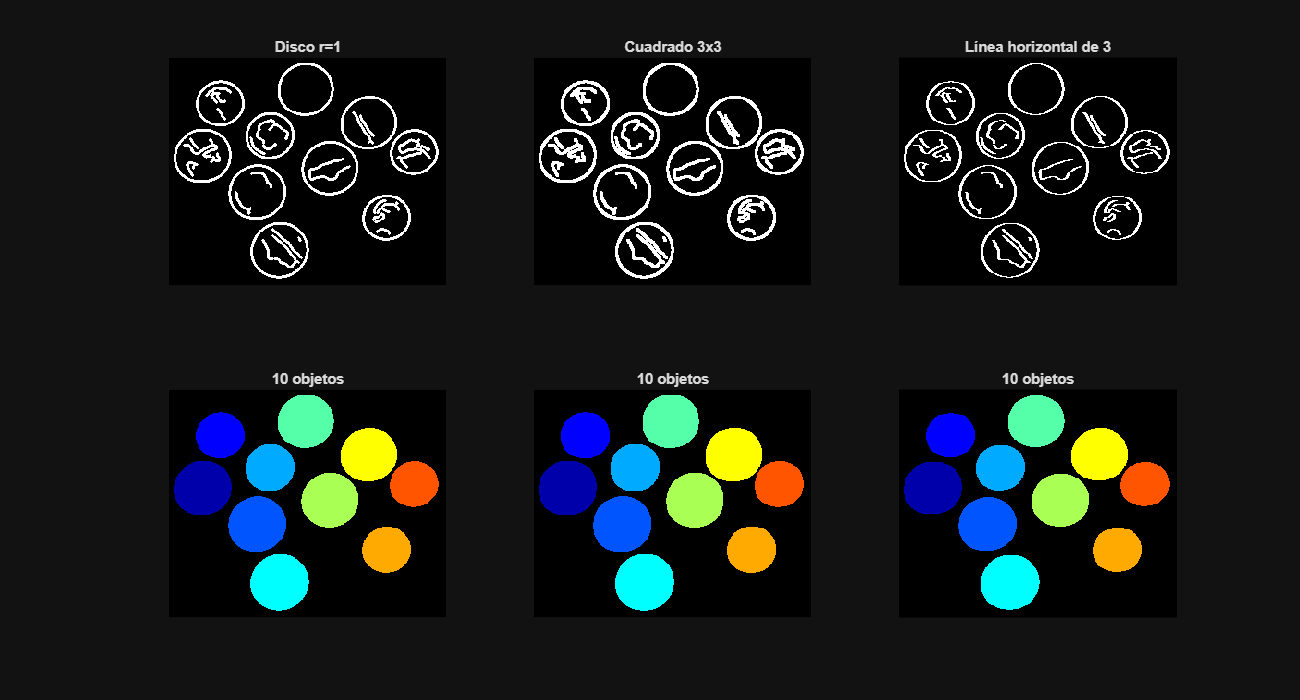

for k = 1:2
    [sinDilatar, nSin] = bwlabel(imfill(bordes{k}, 'holes'));
    [conDilatar, nCon] = bwlabel(imfill(imdilate(bordes{k}, elemento), 'holes'));
    subplot(2,2,(k-1)*2+1), imshow(label2rgb(sinDilatar, 'jet', 'k'));
    title([metodos{k} ' sin dilatar: ' num2str(nSin)]);
    subplot(2,2,(k-1)*2+2), imshow(label2rgb(conDilatar, 'jet', 'k'));
    title([metodos{k} ' con dilatación: ' num2str(nCon)]);
end

% ---- 4) COMPARACIÓN: distintos elementos estructurantes sobre Canny ----
elementos = {strel('disk', 1, 0), strel('square', 3), strel('line', 3, 0)};
nombres = {'Disco r=1', 'Cuadrado 3x3', 'Línea horizontal de 3'};

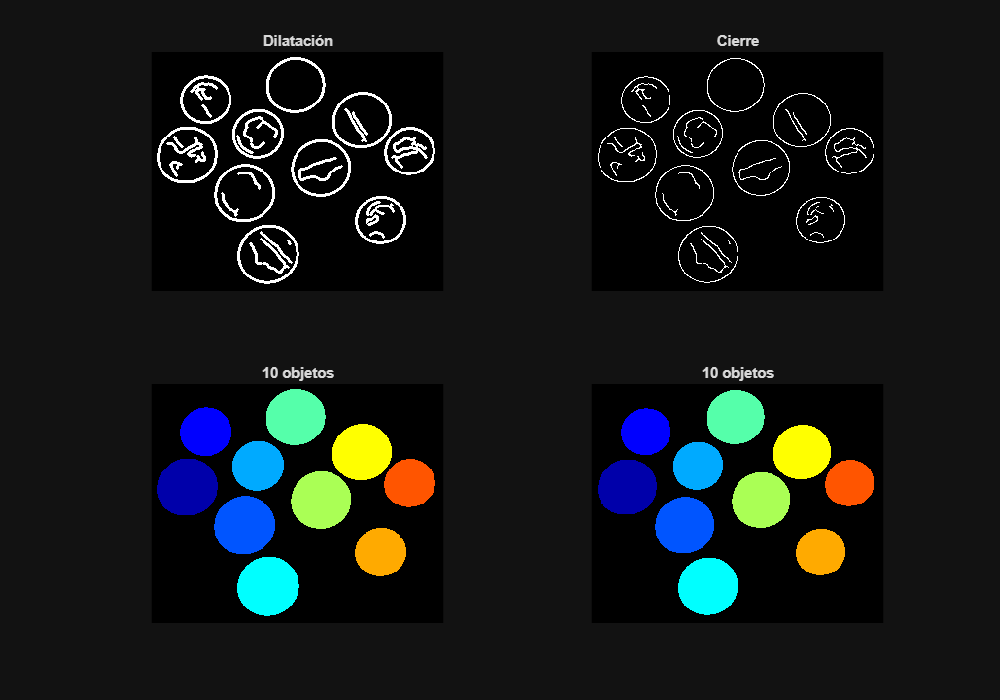

figure('Position', [100 100 1300 700]);
for k = 1:numel(elementos)
    unidos = imdilate(bordesCanny, elementos{k});
    [etiquetas, numero] = bwlabel(imfill(unidos, 'holes'));
    subplot(2,3,k), imshow(unidos); title(nombres{k});
    subplot(2,3,k+3), imshow(label2rgb(etiquetas, 'jet', 'k'));
    title([num2str(numero) ' objetos']);
end

% ---- 5) COMPARACIÓN: dilatación frente a cierre con el mismo disco ----
operaciones = {imdilate(bordesCanny, elemento), imclose(bordesCanny, elemento)};

nombres = {'Dilatación', 'Cierre'};
figure('Position', [100 100 1000 700]);
for k = 1:2
    [etiquetas, numero] = bwlabel(imfill(operaciones{k}, 'holes'));
    subplot(2,2,k), imshow(operaciones{k}); title(nombres{k});
    subplot(2,2,k+2), imshow(label2rgb(etiquetas, 'jet', 'k'));
    title([num2str(numero) ' objetos']);
end

Primero se detectaron los bordes de coins.png con Canny y Sobel. Con los valores iniciales, Canny marca contornos más continuos; usa dos umbrales para conservar los bordes débiles que están conectados con otros más claros. Sobel utiliza un solo umbral y aquí deja más cortes. Los controles permiten comprobar que, al subir los umbrales, desaparecen bordes débiles; al bajarlos, aparecen más detalles y también puede aparecer ruido. Un sigma mayor suaviza más la imagen, aunque puede borrar detalles cercanos.

Después se dilataron los bordes para unir cortes pequeños, se rellenaron los contornos cerrados y se etiquetó cada zona con un color. Con estos parámetros, ambos métodos dan 10 objetos al final. Sin dilatar, Canny ya permite rellenar las 10 monedas; Sobel produce 21 componentes y una moneda queda abierta. Al dilatar, sus bordes se unen y se rellenan las 10. Si un contorno queda abierto, el interior sigue conectado con el fondo y el relleno no entra. Por eso miramos también las imágenes: el número de etiquetas por sí solo no indica si cada moneda quedó bien segmentada.

Al cambiar el elemento de dilatación, el disco, el cuadrado y la línea horizontal dan 10 objetos en este ejemplo, pero unen los bordes de forma distinta. El disco y el cuadrado actúan en varias direcciones; el cuadrado engrosa más las esquinas. La línea favorece los cortes horizontales y puede dejar otros sin cerrar. Si el elemento fuese demasiado grande, también podría juntar monedas vecinas.

Por último, la dilatación y el cierre dan 10 objetos, aunque no dejan el mismo borde. La dilatación lo hace más grueso; el cierre dilata y luego erosiona, de modo que puede unir pequeños cortes conservando mejor la forma. En esta imagen ambos permiten rellenar las monedas. La elección depende de si queremos cerrar los cortes sin engrosar demasiado los objetos.

**3. Detección de rectas utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, detecte y represente los 7 segmentos de recta más largos de la imagen **'despacho1.jpg'**.

- Verifique la función de los parámetros 'FillGap' y 'MinLength' modificando su valor (por ejemplo, mediante *sliders*) y visualizando el resultado. Comente su efecto sobre los segmentos detectados.

- Calcule el número de picos `size(P,1)` y el número de líneas `length(lines)` obtenidas. ¿Son iguales o diferentes? ¿por qué?

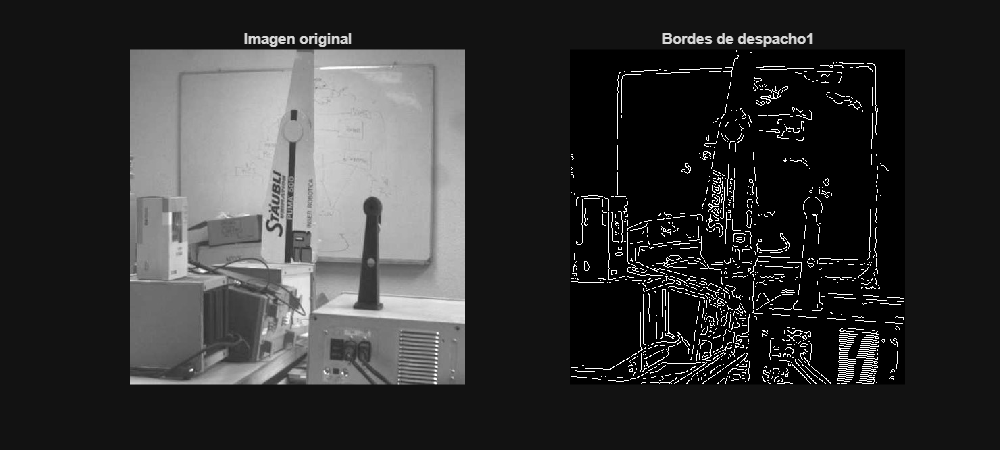


clear all
close all
I = imread('.\Imagenes\despacho1.jpg');

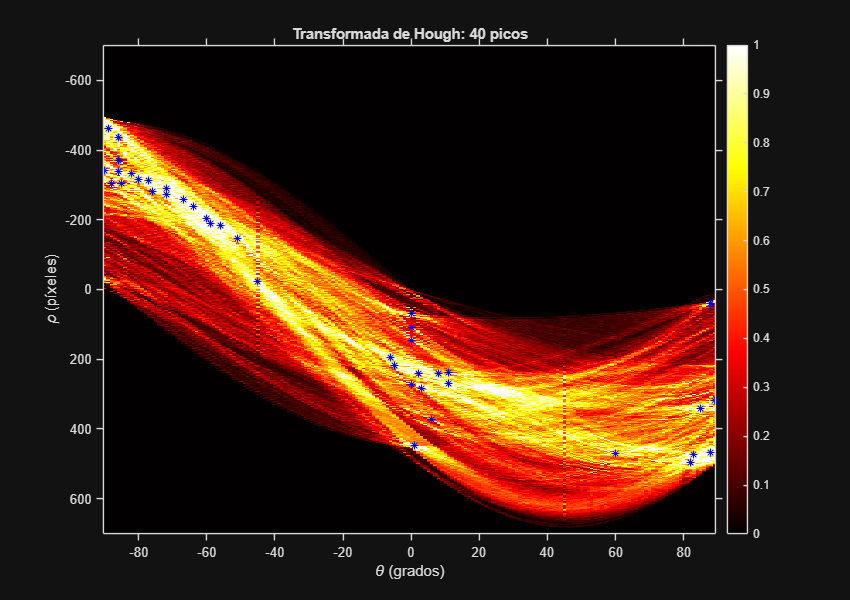

bordes = edge(im2gray(I), 'Canny');
[H, theta, rho] = hough(bordes);

% La transformada cuenta qué rectas pueden pasar por los píxeles de borde.
% Un pico representa una recta candidata; puede contener varios segmentos separados.
P = houghpeaks(H, 40, 'Threshold', ceil(0.3 * max(H(:))));

figure('Position', [100 100 1000 450]);
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(bordes); title('Bordes de despacho1');

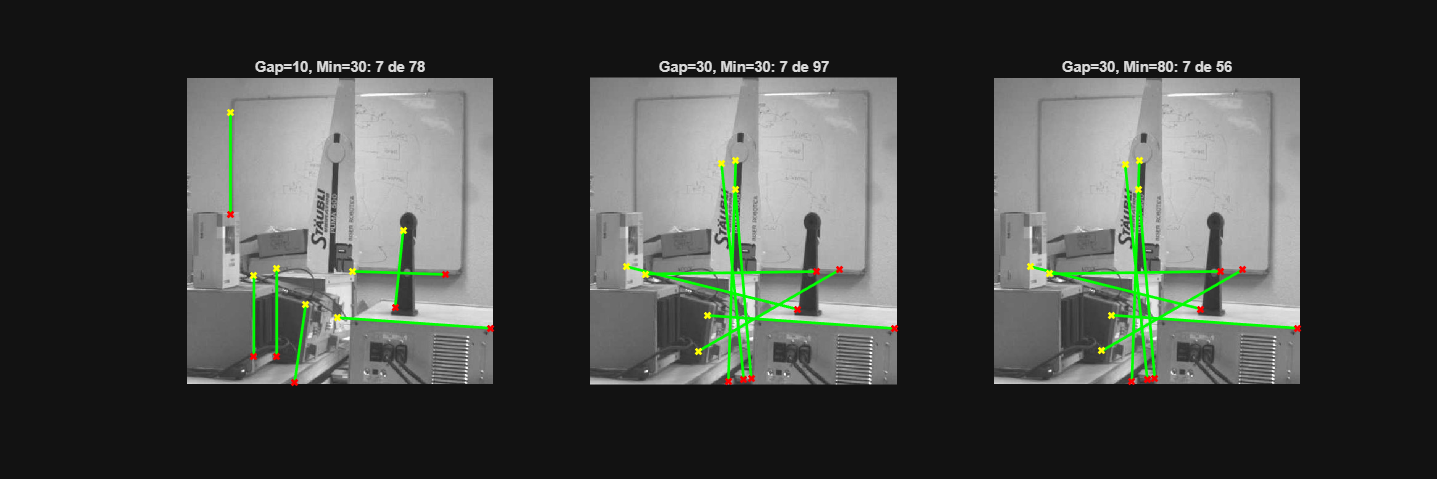

FillGap=10, MinLength=30: 40 picos y 78 segmentos; se muestran 7
FillGap=30, MinLength=30: 40 picos y 97 segmentos; se muestran 7
FillGap=30, MinLength=80: 40 picos y 56 segmentos; se muestran 7



% Aclaramos el acumulador y marcamos sus picos.
figure('Position', [100 100 850 600]);
imshow(imadjust(rescale(H)), 'XData', theta, 'YData', rho, 'InitialMagnification', 'fit');
axis on; axis normal; colormap(gca, hot); colorbar;
hold on
plot(theta(P(:,2)), rho(P(:,1)), 'b*');
hold off
xlabel('\theta (grados)'); ylabel('\rho (píxeles)');
title(['Transformada de Hough: ' num2str(size(P,1)) ' picos']);

% Cambiamos un parámetro cada vez para ver su efecto.
% Filas: [FillGap MinLength]. La primera configuración será el resultado principal.
configuraciones = [10 30; 30 30; 30 80];
figure('Position', [100 100 1500 500]);
for k = 1:size(configuraciones, 1)
    salto = configuraciones(k,1);
    minimo = configuraciones(k,2);
    lines = houghlines(bordes, theta, rho, P, 'FillGap', salto, 'MinLength', minimo);

    % Ordenamos los segmentos por su longitud, no por la intensidad del pico.
    longitudes = zeros(1, length(lines));
    for j = 1:length(lines)
        longitudes(j) = norm(lines(j).point2 - lines(j).point1);
    end
    [~, orden] = sort(longitudes, 'descend');
    elegidos = orden(1:min(7, length(lines))); % evita un error si se detectan menos de 7

    fprintf('FillGap=%d, MinLength=%d: %d picos y %d segmentos; se muestran %d\n', ...
        salto, minimo, size(P,1), length(lines), numel(elegidos));

    subplot(1,3,k), imshow(I); hold on
    for j = elegidos
        puntos = [lines(j).point1; lines(j).point2];
        plot(puntos(:,1), puntos(:,2), 'g-', 'LineWidth', 2);
        plot(puntos(1,1), puntos(1,2), 'yx', 'LineWidth', 2);
        plot(puntos(2,1), puntos(2,2), 'rx', 'LineWidth', 2);
    end
    hold off
    title(sprintf('Gap=%d, Min=%d: %d de %d', salto, minimo, numel(elegidos), length(lines)));
end

Células detectadas con radio entre 7 y 20 píxeles: 25


Partimos de los bordes de despacho1.jpg y calculamos la transformada de Hough. Las zonas más intensas del gráfico indican rectas que reciben más votos de los píxeles de borde; las estrellas azules señalan los 40 picos encontrados. A partir de ellos, houghlines busca tramos en la imagen. Medimos cada tramo entre sus extremos y mostramos los siete más largos de cada configuración en verde, con el inicio amarillo y el final rojo. Así elegimos por longitud y no por la intensidad del pico.

Probamos primero FillGap = 10 y MinLength = 30. Al subir FillGap a 30 se pueden unir tramos separados por huecos mayores; también pueden aparecer más segmentos que superen la longitud mínima, aunque un valor excesivo podría unir partes de objetos distintos. Después, al subir MinLength a 80, se descartan los tramos cortos. En esta imagen se obtienen 78, 97 y 56 segmentos, respectivamente; los siete más largos son los mismos en las dos últimas pruebas.

El número de picos y el de segmentos son diferentes. Un pico señala una recta posible en el acumulador, pero sobre esa recta puede haber varios tramos de borde separados. Además, alguno puede ser demasiado corto para superar MinLength. Por eso contamos todos los segmentos detectados antes de elegir los siete que mostramos.

**4. Detección de circunferencias utilizando la transformada de Hough:**

- Utilizando la transformada de Hough, localice y represente el contorno de las células de la imagen **'blood1.tif'** cuyo radio esté entre 7 y 20 píxeles. Si fuera necesario, considere la posibilidad de umbralizar la imagen y/o de invertirla antes de aplicar la transformada.

- Resalte la célula más grande pintándola de un color diferente.

- ¿Cuántas células ha encontrado?


clear all
close all
I = imread('.\Imagenes\blood1.tif');

% Las células son oscuras respecto al fondo. No hace falta invertir ni umbralizar.
[centros, radios] = imfindcircles(I, [7 20], 'ObjectPolarity', 'dark', 'Sensitivity', 0.85);
numero = numel(radios);

Radio de la mayor célula detectada: 19.26 píxeles


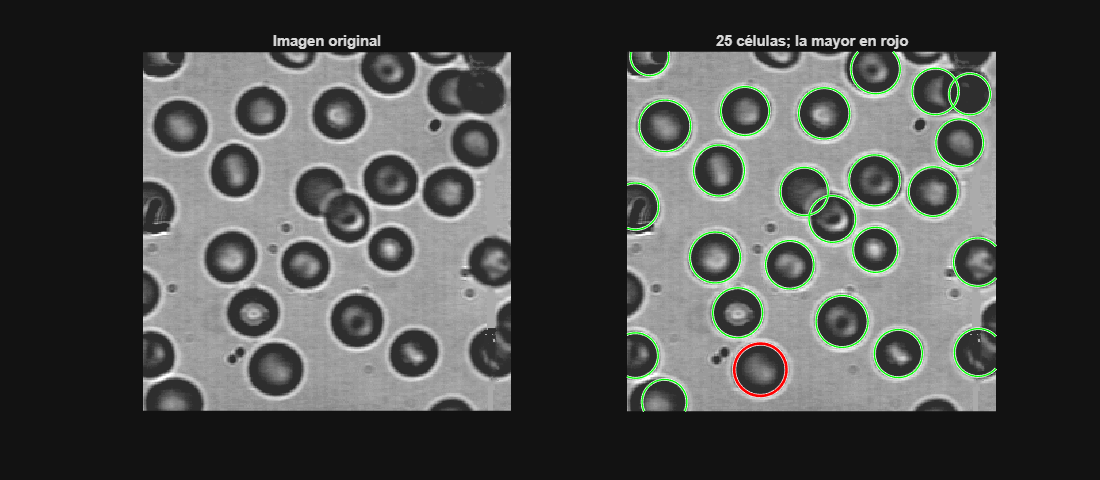

fprintf('Células detectadas con radio entre 7 y 20 píxeles: %d\n', numero);


% Vemos la imagen original al lado de los círculos encontrados.
figure('Position', [100 100 1100 480]);
subplot(1,2,1), imshow(I); title('Imagen original');
subplot(1,2,2), imshow(I); hold on
viscircles(centros, radios, 'Color', 'g', 'LineWidth', 1);
if numero > 0
    [radioMayor, indice] = max(radios);
    viscircles(centros(indice,:), radioMayor, 'Color', 'r', 'LineWidth', 2);
    fprintf('Radio de la mayor célula detectada: %.2f píxeles\n', radioMayor);
end
hold off
title([num2str(numero) ' células; la mayor en rojo']);

Buscamos circunferencias de radio entre 7 y 20 píxeles en blood1.tif. Indicamos polaridad oscura porque las células se ven más oscuras que el fondo. La imagen ya tiene contraste suficiente, así que no hizo falta invertirla ni umbralizarla. Con sensibilidad 0,85 se detectan 25 círculos: se dibujan en verde y el de mayor radio se destaca en rojo. El radio máximo estimado es de aproximadamente 19,26 píxeles y corresponde a la mayor circunferencia detectada dentro del intervalo solicitado, no necesariamente a la célula de mayor tamaño real de toda la imagen. La transformada busca evidencias de contornos circulares, por lo que la superposición y el recorte de algunas células pueden afectar a las detecciones.

Estos 25 circulos destectados corresponden a las detecciones con los parámetros elegidos. Una célula cortada por el borde o solapada con otra puede no formar un círculo claro para el detector. Si aumentamos mucho la sensibilidad, podría encontrar más círculos, pero algunos podrían ser falsos. Por eso comparamos también los contornos dibujados con la imagen original. 